clear, close all, clc


## Problem 1

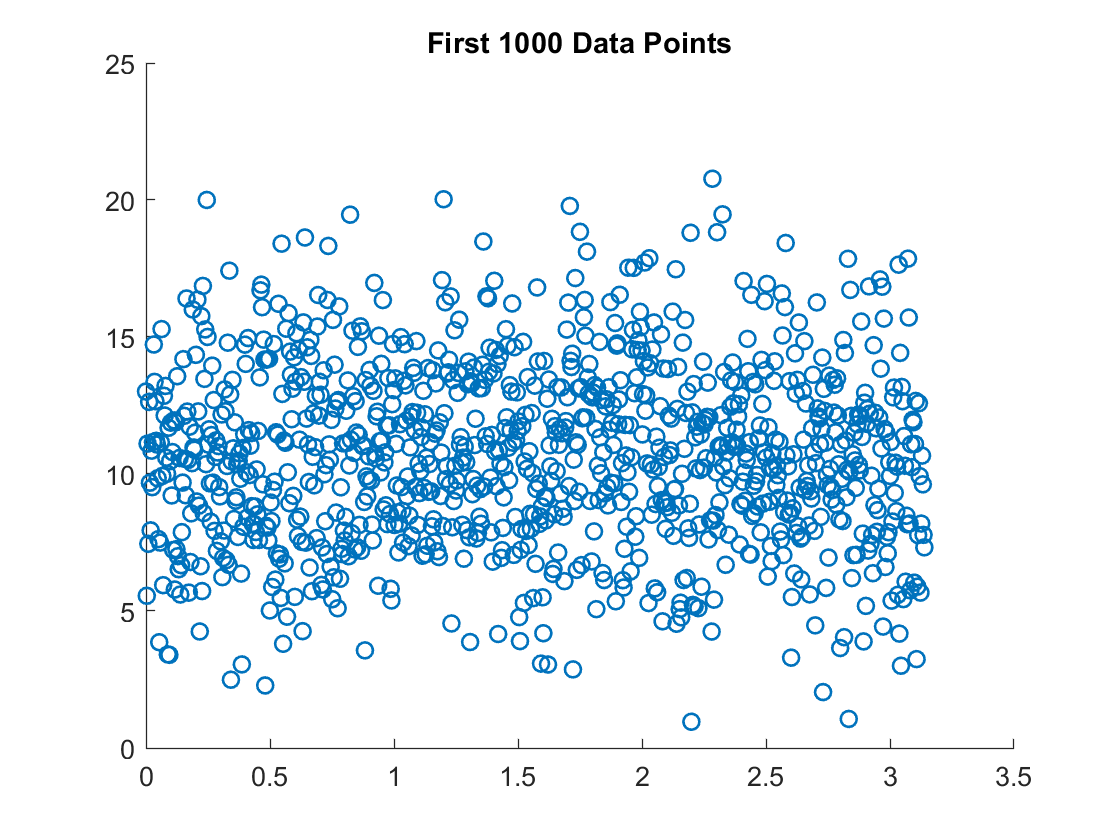


t1 = linspace(0,100*pi, 1e5);
N = 10 + sin(t1);

x = normrnd(0,1,1,1e5).*sqrt(N)+N;


scatter(t1(1:1000),x(1:1000), 'Linewidth',1)
title('First 1000 Data Points')

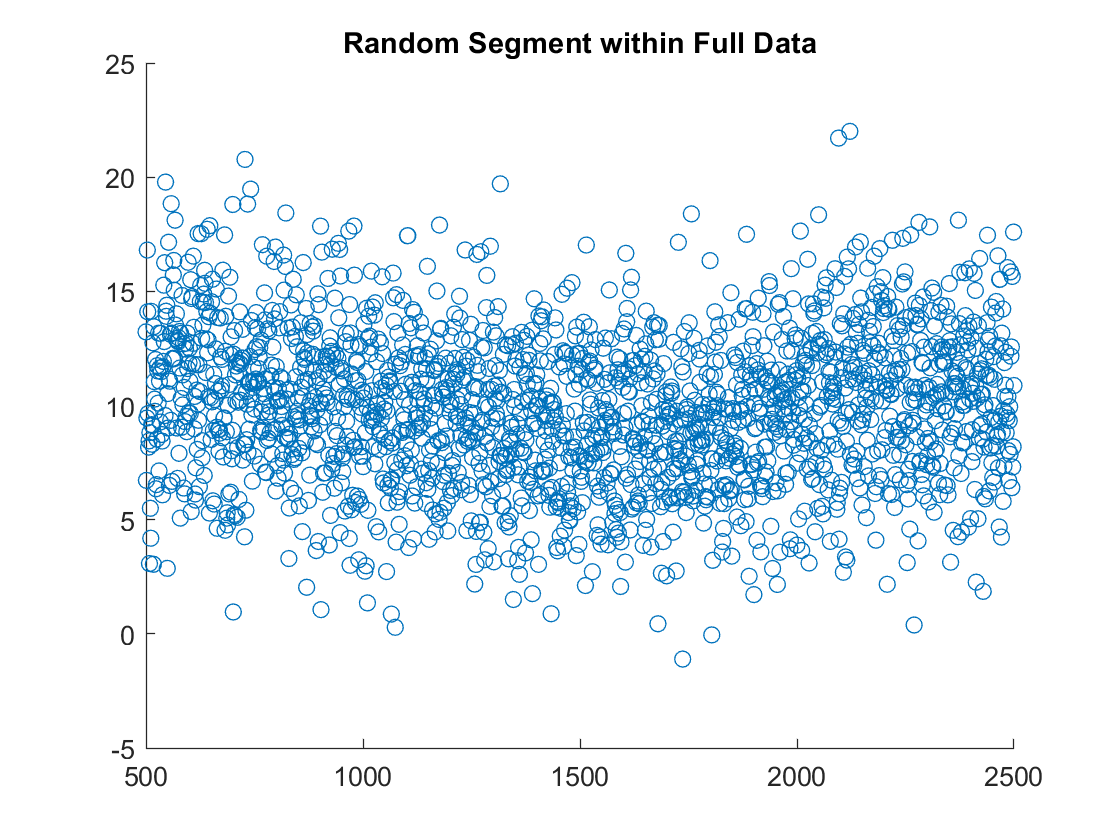


plot_scat([500,2000],x)
title('Random Segment within Full Data')

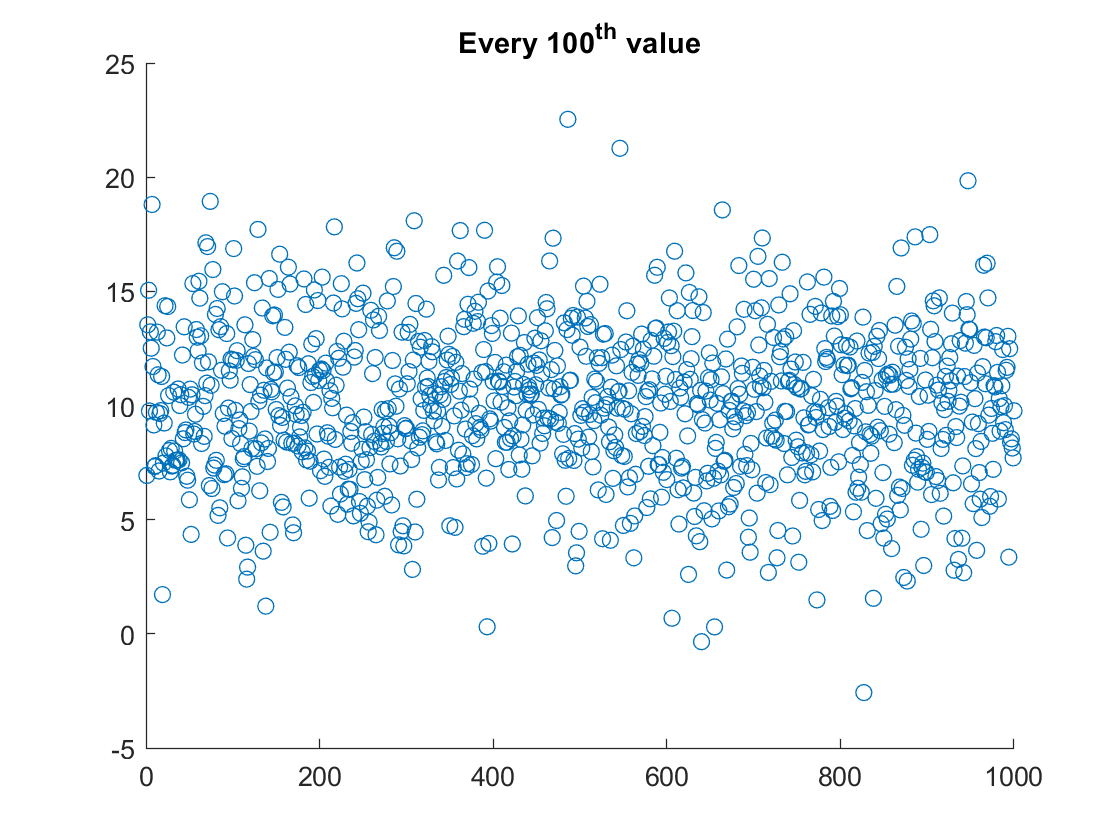


new_x = zeros(1,1000);
for i = 1:1000
    val = 100*i;
    new_x(i) = x(val);
end
scatter(1:1000,new_x)
title('Every 100^{th} value')

## Problem 2

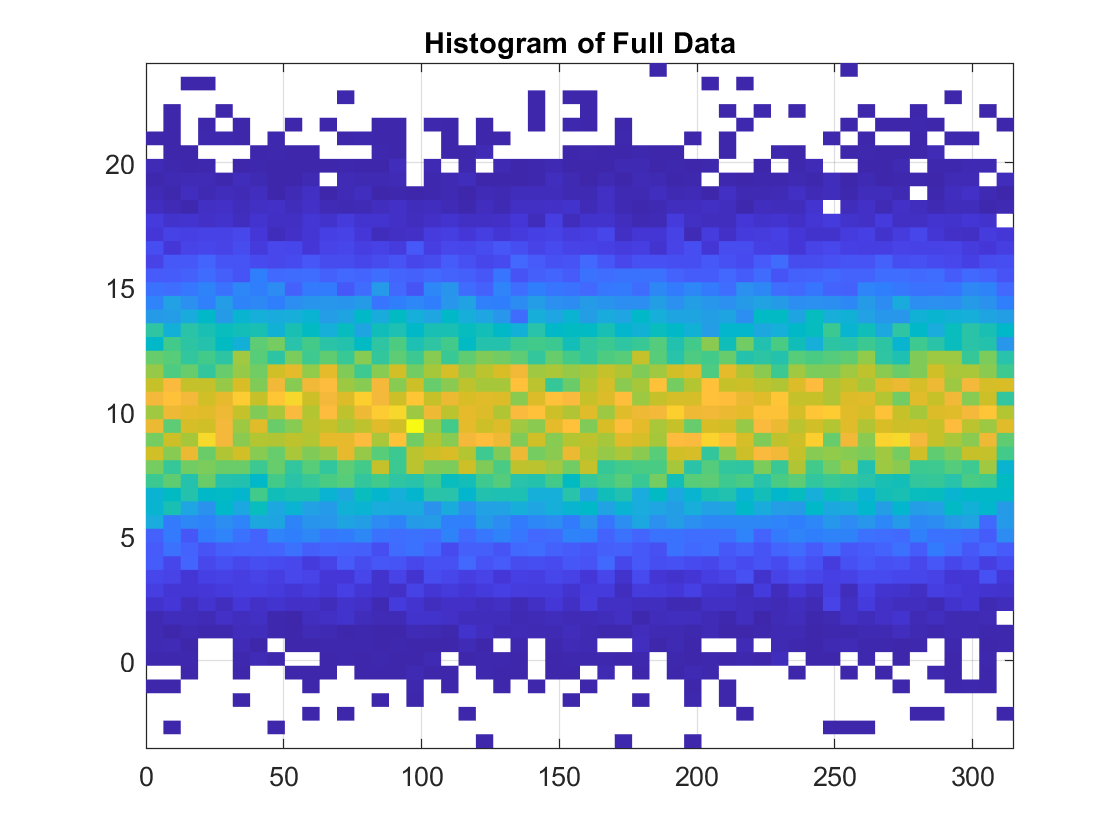

histogram2(t1,x,50,'DisplayStyle', 'tile')
title('Histogram of Full Data')

The histogram is showing the density of points. The color value for each bin represents the number of points that lie within the bin. The X and Y-axis are the same as in the scatter plot.

## Problem 3

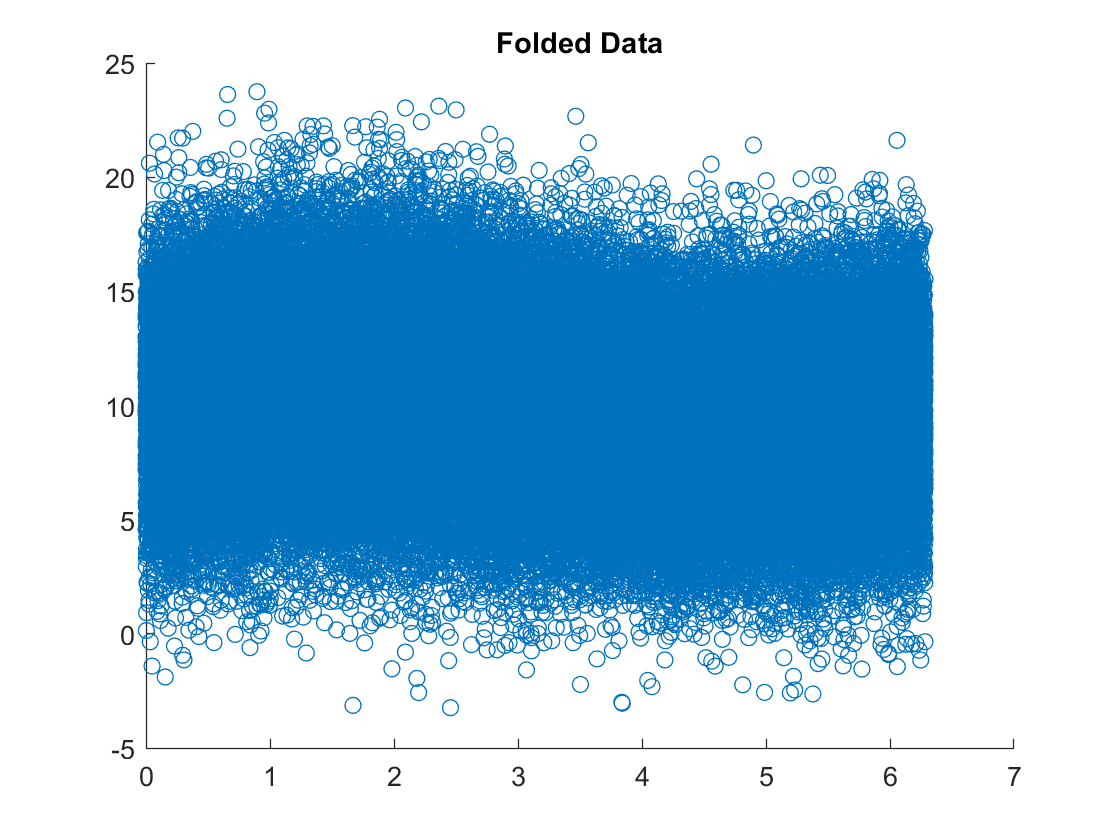

b = mod(t1,2*pi);
scatter(b,x)
title('Folded Data')

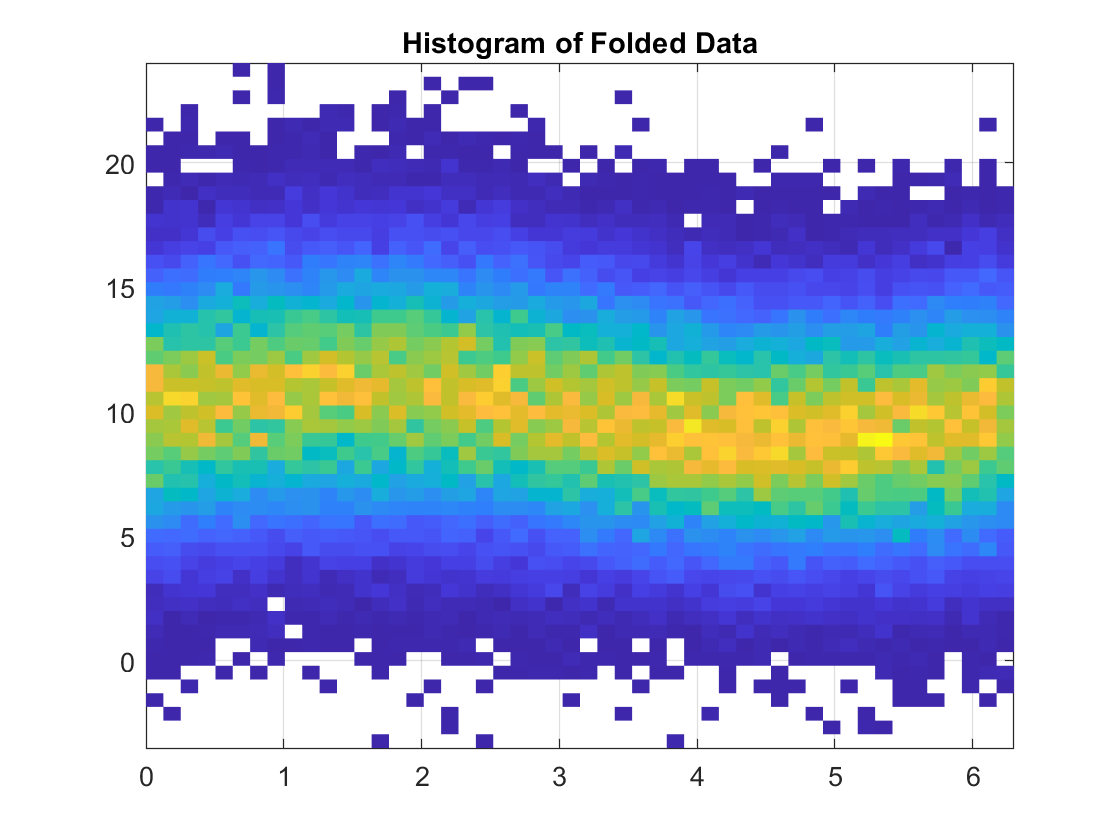


histogram2(b,x,50,'DisplayStyle', 'tile')
title('Histogram of Folded Data')

function [] = plot_scat(range, x)
% range(start_val, length)
end_pnt = range(1)+range(2);
t = linspace(range(1),end_pnt, range(2));
scatter(t,x(range(1):range(1)+range(2)-1))
end